# Turotial: EPI Distortion Correction

# Part 2: Dynamic Distortion Correction = Using EPI-derived Series of $\Delta B_0$ Field Maps

## Computational Steps Overview:

- Defining Inputs

- Calculating Phase Offset from GEFM Reference and EPI Phase Data

- EPI: Phase Offset Removal, Voxel Shift Map Calculation and Dynamic Distortion Correction

- Quality Assurance

## Step 1 - Defining Inputs

Please run through Part 1 of the tutorial first: EPI_DistortionCorrection_Tutorial_SDC_Part1.mlx

working_dir = 'D:\PostDoc_FIL_WCHN\Conferences\ISMRM_2023\DDC_EPI\Tutorial\data_EPI_DC_Tutorial' ;
romeo_path = 'D:\PostDoc_FIL_WCHN\software\mritools\bin';
cd(working_dir)

Let's have a look at the available data.

**3T Gradient Echo Field Map (GEFM):** magnitude and phase difference (1.5x1.5x2.0 ${\textrm{mm}}^3$) 

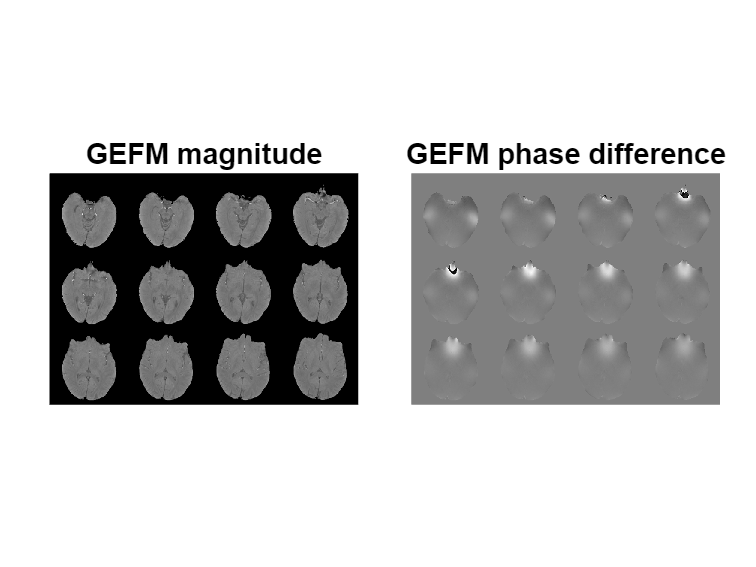

view = 'axial'; 'sagittal'; % pick a view

GEFM_mag = nifti('GEFM_mag.nii').dat(:,:,:) ;
GEFM_phdiff = nifti('GEFM_ph.nii').dat(:,:,:) ;

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM_mag(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM_mag(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
title('GEFM magnitude','FontSize',16)
nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM_phdiff(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM_phdiff(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
title('GEFM phase difference', 'FontSize',16)

**3T 2D Gradient Echo EPI data:** multi-volume **magnitude and phase** data (1.5x1.5x2.0 ${\textrm{mm}}^3$):

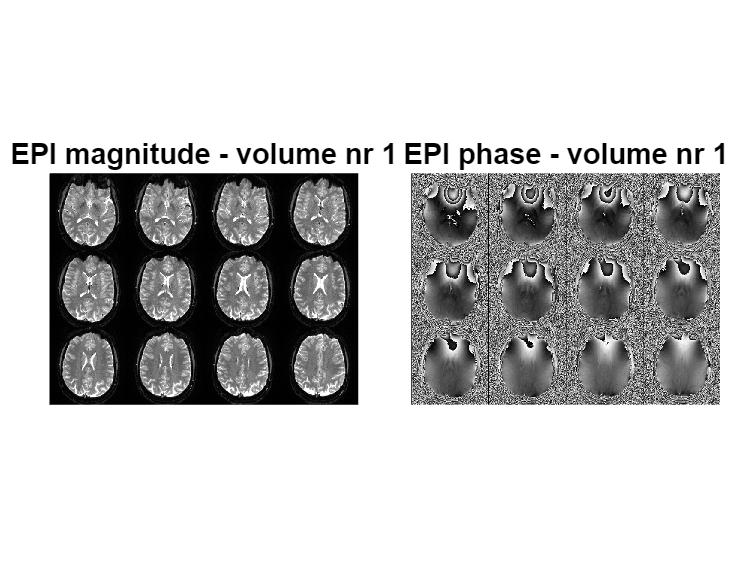

vol_nr = 1 ; % pick a volume
view = 'axial'; 'sagittal'; % pick a view

EPI_mag = nifti(fullfile(working_dir,'EPI','mag','mag.nii')).dat(:,:,:,vol_nr) ;
EPI_ph = nifti(fullfile(working_dir,'EPI','ph','ph.nii')).dat(:,:,:,vol_nr) ;

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
if strcmp(view, 'sagittal')
montage(mat2gray(permute(flip(EPI_mag(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]),[0 1500])); %sagital view
elseif strcmp(view, 'axial')
montage(mat2gray(permute(flip(EPI_mag(:,:,end/2-6:end/2+5),2),[2 1 4 3]),[0 1500])); % axial view
end
title(sprintf('EPI magnitude - volume nr %i', vol_nr),'FontSize',16);

nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(EPI_ph(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))); %sagital view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(EPI_ph(:,:,end/2-6:end/2+5),2),[2 1 4 3]))); % axial view
end
title(sprintf('EPI phase - volume nr %i', vol_nr),'FontSize',16);

## Step 2 - Calculating Phase Offset from GEFM Reference and EPI Phase Data

We will do:

    A. GEFM Calculation and Extrapolation

    B. GEFM Corregistration to EPI Space

    C. EPI Phase Unwrapping

    D. Phase Offset Estimation and Extrapolation

### A. GEFM Calculation and Extrapolation

As in EPI_DistortionCorrection_Tutorial_SDC_Part1.mlx we choose ROMEO [1] for GEFM calculation and smoothn.m [2] for extrapolation:

system(sprintf('%s -p GEFM_ph.nii -m GEFM_mag.nii -o GEFM_ph_unwr.nii -v -B -t 2.46', fullfile(romeo_path, 'romeo')));

Phase loaded!
Mag loaded!
Phase offset correction with MCPC-3D-S set to monopolar
Phase offset correction with MCPC-3D-S turned off (only one echo)
Echoes are 1
TEs are 2.46
Calculate robustmask from magnitude, saved as mask.nii
individual unwrapping is false
echo 1 used as template
perform unwrapping...
unwrapping finished!


GEFM = nifti('B0.nii').dat(:,:,:);
GEFM_extrap = GEFM;
GEFM_extrap(GEFM_extrap==0) = NaN;
GEFM_extrap = smoothn(GEFM_extrap, 1, 'robust');

createNifti(GEFM_extrap, 'GEFM_B0_extrap.nii', nifti('GEFM_ph.nii').mat)

### B. GEFM Corregistration to EPI Space

Corregister GEFM to the closest (in time) EPI volume.

For this dataset GEFM was acquired before the EPI so we take the first volume as reference (nr 01). 

We will use SPM12 [3] Coregister functionality embedded in the following wrapper (available in Supplementary Matierial):

coreg_GEFM2EPI('EPI/mag/mag_01.nii', 'GEFM_mag.nii', 'GEFM_B0_extrap.nii');

Initialising batch system... done.


------------------------------------------------------------------------
02-Jun-2023 19:02:21 - Running job #1
------------------------------------------------------------------------
02-Jun-2023 19:02:21 - Running 'Coregister: Estimate & Reslice'

SPM12: spm_coreg (v7320)                           19:02:21 - 02/06/2023
Completed                               :          19:02:41 - 02/06/2023

SPM12: spm_reslice (v7141)                         19:02:42 - 02/06/2023
Completed                               :          19:02:43 - 02/06/2023
02-Jun-2023 19:02:43 - Done    'Coregister: Estimate & Reslice'
02-Jun-2023 19:02:43 - Done



### C. EPI Phase Unwrapping 

system(sprintf('%s -p EPI/ph/ph.nii -m EPI/mag/mag.nii -o EPI/ph/ph_unwr.nii -t epi -k nomask -q --template 1 -v', fullfile(romeo_path, 'romeo')));

Phase loaded!
Mag loaded!
Echoes are 1:55
TEs are [1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0]
individual unwrapping is false
echo 1 used as template
perform unwrapping...
unwrapping finished!
Calculate and write quality map...


"-k nomask" option in ROMEO unwrapps everything including background noise, we will not mask EPI phase but we will apply masking later on to phase offset in order to extrapolate it.

"-q" option saves quality map, which guides ROMEO unwrapping process, but can be also used as a mask if threshodled and binarized.

In case EPI phase is corrupted by open-ended fringe line artifacts, phase uwnrapping should be performed after phase offset subtraction (as in Step 2.D but in complex domain) rather than before - to remove these artifacts.

Let's have a look at the quality of EPI phase unwrapping.

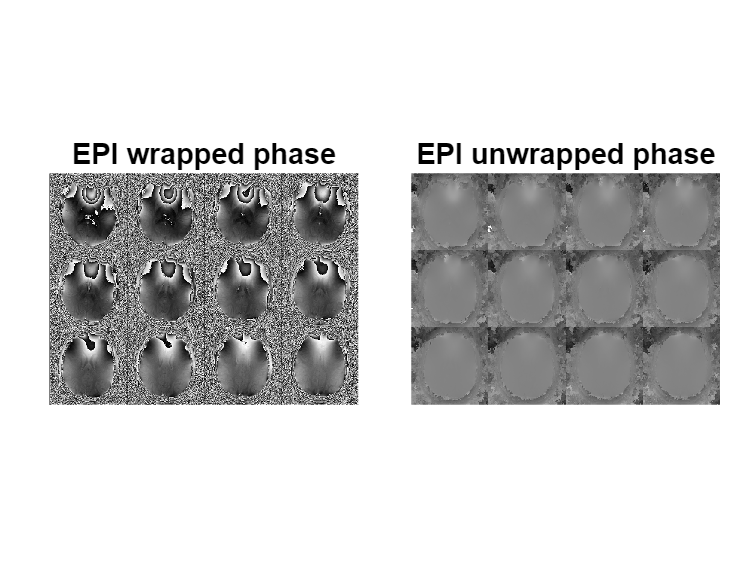

vol_nr = 1 ; % pick a volume
EPI_ph_unwr = nifti(fullfile(working_dir,'EPI','ph','ph_unwr.nii')).dat(:,:,:,vol_nr) ;

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
montage(mat2gray(permute(flip(EPI_ph(:,:,end/2-6:end/2+5),2),[2 1 4 3])));
title('EPI wrapped phase','FontSize',16);
nexttile
montage(mat2gray(permute(flip(EPI_ph_unwr(:,:,end/2-6:end/2+5),2),[2 1 4 3])));
title('EPI unwrapped phase','FontSize',16);

### D. Phase Offset Estimation and Extrapolation

Depending on the type of coil (how many channels?), sequence (what are your gradient delays, eddy currents?) and image reconstruction (e.g. SENSE, GRAPPA + some coil combination) used, a different phase offset may be present in EPI phase. Please mind that Sum of Squares coil combination provides unusable phase images.

Here we have only access to the combined EPI phase, i.e. it was combined using Adaptive Combined method [REF???] with prescan-normalise and no separate channel or raw data available. 

We will thus assume the difference in GEFM and a Field Map from the closest (in time) EPI volume is negligible.

We will estimate phase offset (i.e. $\varphi_0^{\mathrm{fMRI}}$ or p0 in code) as a difference between EPI phase and scaled GEFM:


$$\varphi_0^{\mathrm{fMRI}} =\varphi_{\left(\mathrm{tp}=1\right)}^{\mathrm{fMRI}} -2\pi \cdot \mathrm{TE}\cdot {\Delta \omega }_0^{\mathrm{ref}}$$


Before above subtraction, we will bring ${\Delta \omega }_0^{\mathrm{ref}}$ to the EPI space by "forward-warping".

vol_nr = 1; % our reference EPI volume
TE_epi = 30e-3 ; % EPI echo time in seconds
interp_method = -5 ; % 1 is trilinear, values > 0 are nth order polnomial, values < 0 are nth order sinc ...
EPI_ph_unwr_file = fullfile('EPI','ph','ph_unwr.nii');
GEFM_file = 'coreg2EPI_GEFM_B0_extrap.nii' ;
VSM_SDC_file = 'coreg2EPI_VSM_SDC.nii';

% warp field initialisation:

[Mx, My, Mz] = size(nifti(EPI_ph_unwr_file).dat(:,:,:,1)); 
[x,y,z] = ndgrid(1:Mx,1:My,1:Mz); 
F_warp_init = [x(:) y(:) z(:)]; 

% warp field including VSM with opposite sign to distort to EPI space:

VSM_SDC = nifti(VSM_SDC_file).dat(:,:,:);
F_warp = F_warp_init;
F_warp(:,2) = F_warp_init(:,2) + reshape(-VSM_SDC,[Mx*My*Mz,1]);

% "forward-warping" GEFM to EPI space:

GEFM_warped = reshape(spm_sample_vol(spm_vol(GEFM_file),...
        F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);

% estimation of phase offset:

EPI_ph_unwr = nifti(EPI_ph_unwr_file).dat(:,:,:,vol_nr) ;
p0 = EPI_ph_unwr - 2*pi*TE_epi*GEFM_warped ;

How does our phase offset look like?

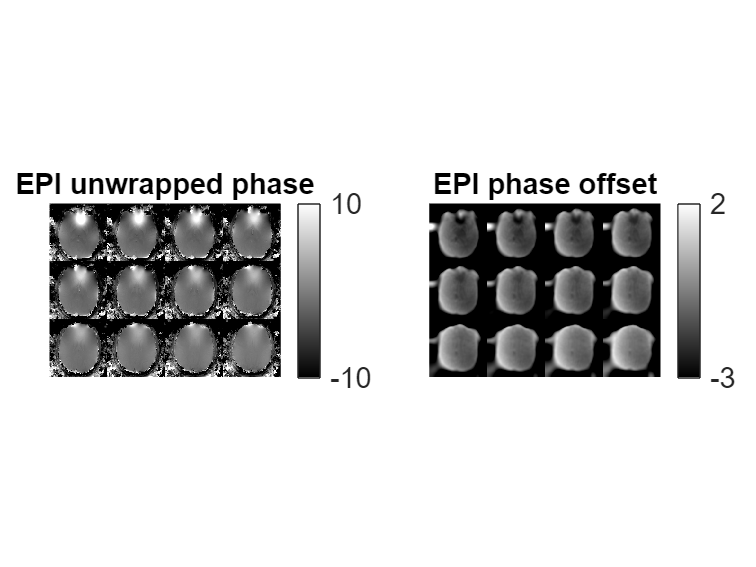

EPI_ph_unwr = nifti(fullfile(working_dir,'EPI','ph','ph_unwr.nii')).dat(:,:,:,vol_nr) ;
ph_scale = [-10 10];
p0_scale = [-3 2];

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile 
montage(mat2gray(permute(flip(EPI_ph_unwr(:,:,end/2-6:end/2+5),2),[2 1 4 3]),ph_scale));
colorbar('Ticks',[0 1],'TickLabels',{ph_scale},'FontSize',16);
title('EPI unwrapped phase','FontSize',16);

nexttile
montage(mat2gray(permute(flip(p0(:,:,end/2-6:end/2+5),2),[2 1 4 3]),p0_scale));
colorbar('Ticks',[0 1],'TickLabels',{p0_scale},'FontSize',16);
title('EPI phase offset','FontSize',16);

There is a small left-right gradient visible in the phase offset - this is most probably because of non-compensated pashe accumulation due to readout gradient delay. The more local minimum close to sinuses most probably comes from the difference between GEFM and EPI field map, which we assumed was small. We won't be able to unwrap any differences which occured between GEFM and 1st volume of EPI, but we will be able to unwrap any dynamic changes happening between the EPI volumes.

To minimize noise amplification and to remove residual structural information from the phase offset $\varphi_0^{\textrm{fMRI}}$ we will smooth and extrapolate it [4]:

qmask = nifti(fullfile(working_dir,'EPI','ph','quality.nii')).dat(:,:,:) ;
qmask = imbinarize(qmask,0.4);
qmask = imfill(qmask,8,'holes') ;

p0(qmask==0) = NaN ;
p0 = smoothn(p0, 1, 'robust');

Above, we generated a mask by thresholding a "quality map" generated by the ROMEO toolbox. Quality map shows a summed score of phase and magnitude coherency between neighbouring voxels [1].

A tip: In this particular case the phase offset has no large wraps or open-ended fringe lines. This doesn't have to be the case. If we plan to do phase uwnrapping after phase offset subtraction we need to preserve 2$\pi$ differences at wrap boundaries, which are then detected by an unwrapping algotrithm. We can do it by complex-domain smoothing:

% p0_imag = imag(exp(1i*p0)) ;
% p0_real = real(exp(1i*p0)) ;
% p0_imag = smoothn(p0_imag, 4) ;
% p0_real = smoothn(p0_real, 4) ;
% p0 = angle(p0_real + 1i*p0_imag) ;

## Step 3 - EPI: Phase Offset Removal, Voxel Shift Map Calculation and Dynamic Distortion Correction

Phase offset, $\varphi_0^{\textrm{fMRI}}$, does not change subtantially during the fMRI run (i.e. won't introduce erroneous voxel shifts if assumed static), even if some motion is present.

That means we can subtract it from each volume of EPI phase to create a series of EPI-based field maps capturing dynamic changes in the field [4]:


$${\Delta \omega }_0^{\textrm{fMRI}} \left(\textrm{tp}\right)=\frac{\varphi_{\left(\textrm{tp}\right)}^{\textrm{fMRI}} -\varphi_0^{\textrm{fMRI}} }{2\pi \cdot \textrm{TE}}$$


Similarily as in Part 1 of the tutorial, the relationship between Voxel Shift Map (VSM) and a Field Map (i.e. Frequency Map) is as following:


$${\textrm{VSM}}^{\textrm{fMRI}} \left(\textrm{tp}\right)=\frac{{\Delta \omega }_0^{\textrm{fMRI}} \left(\textrm{tp}\right)\cdot M_{\textrm{PE}} \cdot t_{\textrm{esp}} \cdot D_{\textrm{PE}} }{R}\;\left\lbrack \textrm{voxels}\right\rbrack$$


where:

$M_{\textrm{PE}}$ - Matrix size in PE direction

$t_{\textrm{esp}}$   - Echo spacing time, e.g. for trapezoid gradient form: 1 x flat top time + 2 x ramp up time

$R$     - Correction factor accounting any acceleration or segmentation reducing distortions, i.e.  $t_{\textrm{esp}}$/$R$ is the "effective echo spacing"

$D_{\textrm{PE}}$ - direction of phase encoding, it's either -1 or 1 depending on the convention. For our data -1 means acquisition in direction Anterior --> Posterior.

Above steps (calculation of ${\Delta \omega }_0^{\textrm{fMRI}}$ and ${\mathrm{VSM}}^{\mathrm{fMRI}}$), together with unwarping can be written in a single loop:

vol_nr = 1:55 ; % choose the range of volumes you want to unwrap

% parameters for VSM creation and interpolation:

t_esp = 0.78*1e-3; % in seconds
R = 2; % this EPI was acquired with 2-fold in-plane acceleration
PE_dir = -1; % phase encoding direction, in this case -1 for AP and 1 for PA
interp_method = -5 ; % 1 is trilinear, values > 0 are nth order polnomial, values < 0 are nth order sinc ...

EPI_ph_file = fullfile('EPI','ph','ph_unwr.nii');
EPI_mat = nifti(EPI_ph_file).mat ;

% warp field initialisation:

[Mx, My, Mz] = size(nifti(EPI_ph_file).dat(:,:,:,1)); 
[x,y,z] = ndgrid(1:Mx,1:My,1:Mz); 
F_warp_init = [x(:) y(:) z(:)]; 

EPI_DDC = zeros(Mx,My,Mz);
for t = vol_nr 
    
    % subtraction of phase offset from EPI phase:

    EPI_ph_unwr = nifti(EPI_ph_file).dat(:,:,:,t) ;
    EPI_FM = (EPI_ph_unwr - p0)/(2*pi*TE_epi) ;
    
    % Voxel Shift Map calculation:

    VSM = EPI_FM*My*t_esp*PE_dir/R ;
    VSM = smoothn(VSM, 1,'robust') ; % moderate smoothing to avoid noise propagation
    VSM_file = sprintf('VSM_DDC_%02.f.nii',t);
    createNifti(VSM, VSM_file, EPI_mat)

    % calculating warp field:

    F_warp = F_warp_init;
    F_warp(:,2) = F_warp_init(:,2) + reshape(VSM,[Mx*My*Mz,1]);

    % calculating Jacobian determinant (in distortion-free space):

    VSM = reshape(spm_sample_vol(spm_vol(VSM_file),...
        F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);
    VSM_grad = (circshift(VSM,1,2)-circshift(VSM,-1,2))/2 ;
    VSM_grad(~isfinite(VSM_grad))=0;
    J_field = 1 + VSM_grad ;

    % application of warp field and interpolation
    
    EPI_file = fullfile('EPI/mag',sprintf('mag_%02.f.nii',t)) ;
    fprintf('Unwarping %s \n', EPI_file)

    EPI_DDC = reshape(spm_sample_vol(spm_vol(EPI_file),...
        F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);
    EPI_DDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_ddc.nii',t)) ;
    createNifti(EPI_DDC, EPI_DDC_file, EPI_mat)

    % optional Jacobian intensity modulation:

    EPI_DDC_jac = EPI_DDC.*J_field ;
    EPI_DDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_ddc_jac.nii',t)) ;
    createNifti(EPI_DDC_jac, EPI_DDC_file, EPI_mat)
    

end

Unwarping EPI\mag\mag_01.nii 
Unwarping EPI\mag\mag_02.nii 
Unwarping EPI\mag\mag_03.nii 
Unwarping EPI\mag\mag_04.nii 
Unwarping EPI\mag\mag_05.nii 
Unwarping EPI\mag\mag_06.nii 
Unwarping EPI\mag\mag_07.nii 
Unwarping EPI\mag\mag_08.nii 
Unwarping EPI\mag\mag_09.nii 
Unwarping EPI\mag\mag_10.nii 
Unwarping EPI\mag\mag_11.nii 
Unwarping EPI\mag\mag_12.nii 
Unwarping EPI\mag\mag_13.nii 
Unwarping EPI\mag\mag_14.nii 
Unwarping EPI\mag\mag_15.nii 
Unwarping EPI\mag\mag_16.nii 
Unwarping EPI\mag\mag_17.nii 
Unwarping EPI\mag\mag_18.nii 
Unwarping EPI\mag\mag_19.nii 
Unwarping EPI\mag\mag_20.nii 
Unwarping EPI\mag\mag_21.nii 
Unwarping EPI\mag\mag_22.nii 
Unwarping EPI\mag\mag_23.nii 
Unwarping EPI\mag\mag_24.nii 
Unwarping EPI\mag\mag_25.nii 
Unwarping EPI\mag\mag_26.nii 
Unwarping EPI\mag\mag_27.nii 
Unwarping EPI\mag\mag_28.nii 
Unwarping EPI\mag\mag_29.nii 
Unwarping EPI\mag\mag_30.nii 
Unwarping EPI\mag\mag_31.nii 
Unwarping EPI\mag\mag_32.nii 
Unwarping EPI\mag\mag_33.nii 
Unwarping 

## Step 4 - Quality Assurance (QA)

Don't assume distortion correction worked as intended, perform a tailored QA analysis.

Examples of possible QA procedures:

- Visual inspection 

              a. comparison before and after unwarping

              b. comparison of a reference structural scan with original, and corrected EPI data.

           2. Dice coefficient for grey matter masks.

           3.  tSNR comparison with and without correction

Good examples of quality assurance can be found in Ref. [5].

**Visual inspection - before and after unwarping**

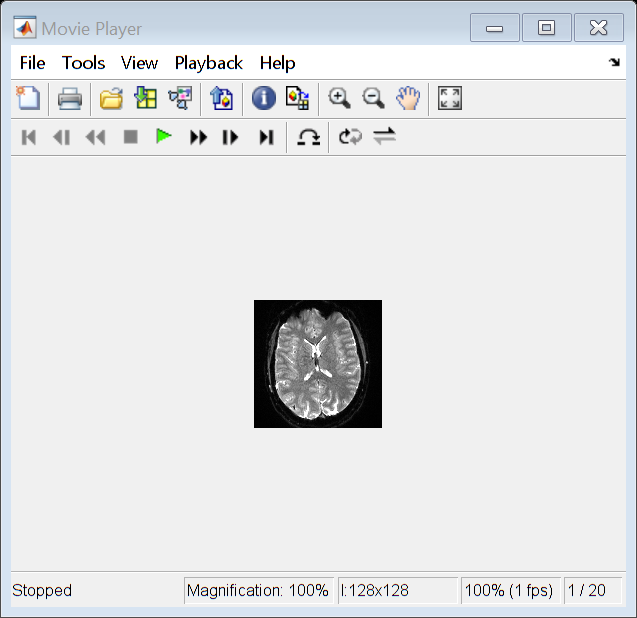

vol_nr = 1 ; % pick a volume
slice = 28 ; % pick a slice

EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_DDC = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_ddc.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_DDC_jac = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_ddc_jac.nii',vol_nr))).dat(:,:,:) ;

EPI_noDC_DDC = cat(3, flip(EPI(:,:,slice),2), flip(EPI_1vol_DDC(:,:,slice),2)) ;
EPI_noDC_DDC = repmat(EPI_noDC_DDC, [1 1 10]);
implay(mat2gray(imrotate(EPI_noDC_DDC,-90),[0 1500]), 1)

**Visual inspection - with and without Jacobian intensity correction**

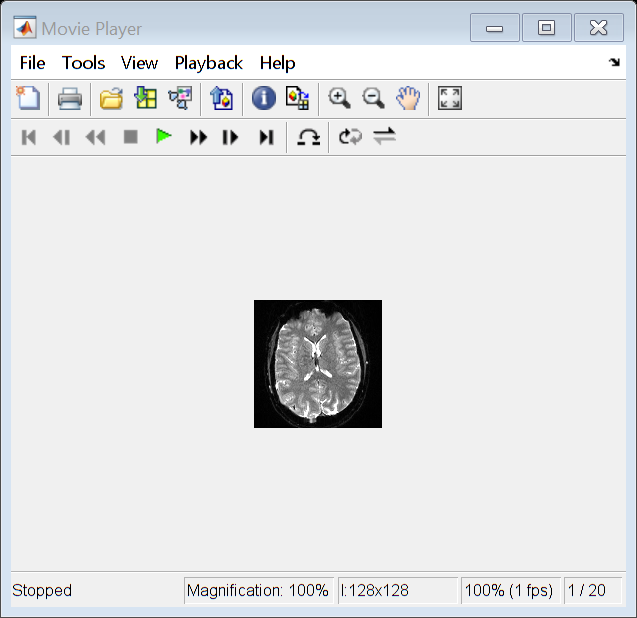

EPI_DDC_DDCjac = cat(3, flip(EPI_1vol_DDC(:,:,slice),2), flip(EPI_1vol_DDC_jac(:,:,slice),2)) ;
EPI_DDC_DDCjac = repmat(EPI_DDC_DDCjac, [1 1 10]);
implay(mat2gray(imrotate(EPI_DDC_DDCjac,-90),[0 1500]), 1)

**Visual inspection - structural vs EPI**

In this case as a structural scan a Gradient Echo was used with same resolution and TE (30ms) as EPI. 

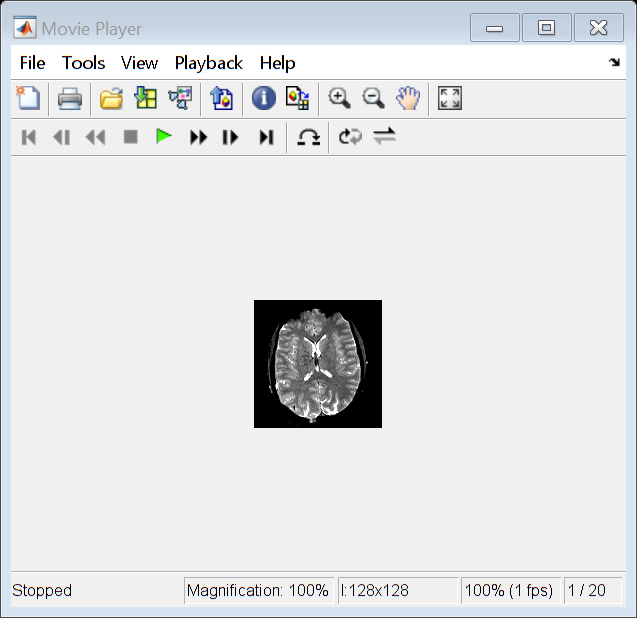

vol_nr = 1 ; % pick a volume
slice = 28 ; % pick a slice
view = 'axial'; 'saggital' ; % pick a view
DC_case = 'DDC' ;'noDC' ; % pick if you want to look at distorted (noDC) or unwarped (DDC) data

if strcmp(DC_case, 'noDC')
    EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
    structural = nifti(fullfile(working_dir, 'struct_coreg2EPI_mean_noDC.nii')).dat(:,:,:);
elseif strcmp(DC_case, 'DDC')
    EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_ddc.nii',vol_nr))).dat(:,:,:) ;
    structural = nifti(fullfile(working_dir, 'struct_coreg2EPI_mean_DDC.nii')).dat(:,:,:);
end
structural(~isfinite(structural))=0;

if strcmp(view,'axial')
    EPI_DDC_structural = cat(3, mat2gray(squeeze(flip(EPI(:,:,slice),2)),[200 1500]), mat2gray(squeeze(flip(structural(:,:,slice),2)),[400 1500])) ;
    EPI_DDC_structural = repmat(EPI_DDC_structural, [1 1 10]);
elseif strcmp(view, 'sagittal')
    EPI_DDC_structural = cat(3, mat2gray(squeeze(flip(EPI(slice,:,:),3)),[200 1500]), mat2gray(squeeze(flip(structural(slice,:,:),3)),[400 1500])) ;
    EPI_DDC_structural = repmat(EPI_DDC_structural, [1 1 10]);
end

implay(imrotate(EPI_DDC_structural,-90), 1)

## Dice Coefficient

Dice coefficient = "overlap" of Gray Matter (GM) masks, i.e.

**dice = 2 (intersected GM region)/(sum of GM regions from image A and image B)**.

Let's load precalculated GM probability maps (SPM12 Segment tool) for structural reference and EPIs.

A wrapper for SPM12 Segment is provided in Supplementary material.

 We will threshold and binarize GM probability maps and calculate pair-wise Dice Coefficients:

GM_threshold = 0.5 ;

% loading precalculated GM probability maps:

struct_GM = nifti(fullfile(working_dir,'struct_GM_coreg2EPI_mean_noDC.nii')).dat(:,:,:);
struct_GM_DDC = nifti(fullfile(working_dir,'struct_GM_coreg2EPI_mean_DDC.nii')).dat(:,:,:);
struct_GM_DDCjac = nifti(fullfile(working_dir,'struct_GM_coreg2EPI_mean_DDC_jac.nii')).dat(:,:,:);
EPI_GM = nifti(fullfile(working_dir,'EPI/mag','c1mag_mean.nii')).dat(:,:,:) ;
EPI_GM_DDC = nifti(fullfile(working_dir,'EPI/mag','c1mag_ddc_mean.nii')).dat(:,:,:) ;
EPI_GM_DDCjac = nifti(fullfile(working_dir,'EPI/mag','c1mag_ddc_jac_mean.nii')).dat(:,:,:) ;

% creating GM masks:

struct_GM = imbinarize(struct_GM, GM_threshold);
struct_GM_DDC = imbinarize(struct_GM_DDC, GM_threshold);
struct_GM_DDCjac = imbinarize(struct_GM_DDCjac, GM_threshold);
EPI_GM = imbinarize(EPI_GM, GM_threshold);
EPI_GM_DDC = imbinarize(EPI_GM_DDC, GM_threshold);
EPI_GM_DDCjac = imbinarize(EPI_GM_DDCjac, GM_threshold);

% calculating pair-wise Dice Coefficients:

struct_EPI_dice = dice(struct_GM, EPI_GM)

struct_EPI_dice = 0.7750

struct_EPI_DDC_dice = dice(struct_GM, EPI_GM_DDC)

struct_EPI_DDC_dice = 0.7912

struct_EPI_DDCjac_dice = dice(struct_GM_DDCjac, EPI_GM_DDCjac)

struct_EPI_DDCjac_dice = 0.7921

## References:

[1] Dymerska, Barbara, and Eckstein, Korbinian, et al. "Phase unwrapping with a rapid opensource minimum spanning tree algorithm (ROMEO)." *Magnetic resonance in medicine* 85.4 (2021): 2294-2308.

Executables and code: [https://github.com/korbinian90/ROMEO](https://github.com/korbinian90/ROMEO)

Exemplary data: [https://dataverse.harvard.edu/dataverse/ROMEO](https://dataverse.harvard.edu/dataverse/ROMEO)

[2] [https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn](https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn)

[3] [https://github.com/spm/](https://github.com/spm/)

[4] Dymerska, Barbara, et al. "A method for the dynamic correction of B0-related distortions in single-echo EPI at 7 T." *Neuroimage* 168 (2018): 321-331.

[5] Malekian et al, [**bioRxiv.org**](https://www.biorxiv.org/)** - add link**

[https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection](https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection)

## Acknowledgements

The Wellcome Centre for Human Neuroimaging is supported by core funding from the Wellcome [203147/Z/16/Z].